%computation domain
nz=501; nx=501;

%marmousi model
nx_m=281; nz_m=1361;
h=10; %meters
dx=h;

% fileID = fopen('vp.12.5m');
% vp0 = fread(fileID,'single');
% vp1 = reshape(vp0,nx_m,nz_m);
% vp = vp1(1:nx,600:600+nz-1);

% fileID = fopen('rho.12.5m');
% rho0 = fread(fileID,'single');
% rho1 = reshape(rho0,nx_m,nz_m);
% rho = rho1(1:nx,600:600+nz-1)/1000;

% global xp1 x xm1 zp1 z zm1;
[xp1, x, xm1, zp1, z, zm1] = initialize_D(nx,nz);

%time steps
nt=800; %1000;
dt=0.002; %sec
t0=0;

%peak frequency
fp=8; %Hz

%velocity range
vp=2000*ones(nz,nx);
vp(3/5*nz:end,:)=3000;

vs=vp./1.7;
alpha = vs./vp;
% rho=1;
rho = 1*ones(nz,nx);
rho(3/5*nz:end,:)= 2;

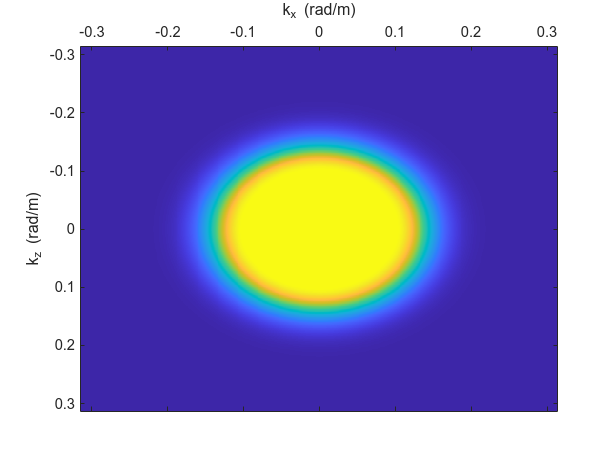

%cmin=625.;
%cmax=1750.;
Q=50;
%Q=1000;
t_interval=20;
nt_small=nt/t_interval;

%source location
isz=round(nz/2); isx=round(nx/2);

kx = 2*pi*(-nx/2:nx/2-1) / (h*nx);   % kx in rad/m
kz = 2*pi*(-nz/2:nz/2-1) / (h*nz);   % kz in rad/m


[KX, KZ] = meshgrid(kx, kz);
K = sqrt(KX.^2 + KZ.^2);              % absolute wavenumber

k_cut = 2*pi*fp/min(vp,[],"all")*4;  % cutoff wavenumber (rad/m)
% mask = double(K <= k_cut);             % low-pass filter mask
mask = zeros(size(K));

% 完全保留区域：K <= k_cut
mask(K <= k_cut) = 1;

% 过渡区域：K > k_cut，平滑衰减
sigma_filter=0.5;
idx = (K > k_cut);
mask(idx) = exp( - ((K(idx) - k_cut) / (sigma_filter * k_cut)).^2 );
figure
imagesc(kz,kx,mask)
xlabel('k_x (rad/m)'); ylabel('k_z (rad/m)');set(gca,'xaxisLocation','top')

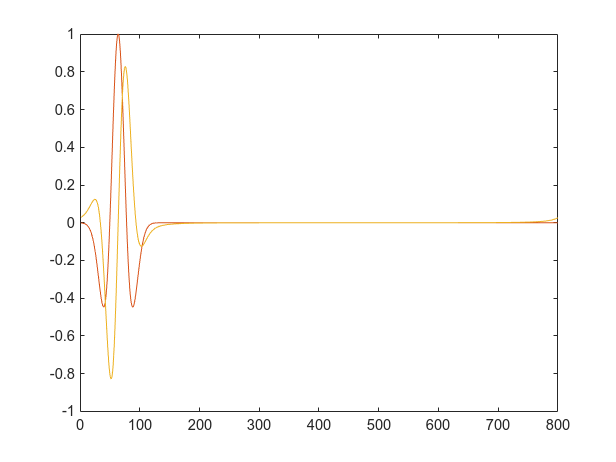


%source time function
figure
wl=ricker(fp,dt,nt,t0);
plot(wl); hold on; 
plot(real(hilbert(wl)));
plot(imag(hilbert(wl)));

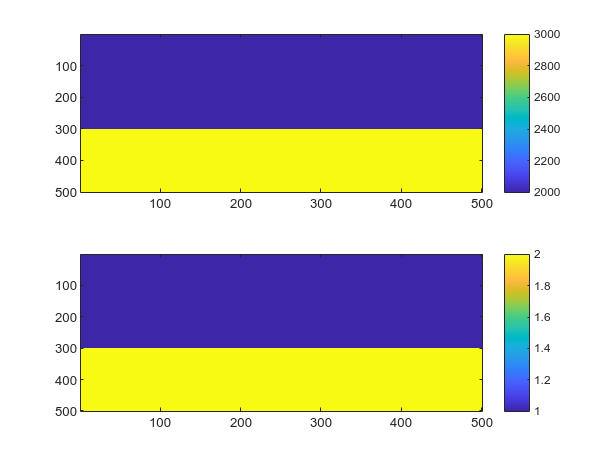

subplot(2,1,1)
imagesc(vp)
colorbar
subplot(2,1,2)
imagesc(rho)
colorbar

[a_x00, a_z00, p00]=modeling_AC({vp,vs,rho,alpha,Q,mask},[0 0],{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1},t_interval,2);

NO Dispersion
NO Dissipation


it = 100

ans = 0

ans = 0.6982 + 0.0035i

it = 200

ans = 0

ans = 0.4216 - 0.3254i

it = 300

ans = 0

ans = 0.4334 - 0.2460i

it = 400

ans = 0

ans = 0.4236 - 0.0770i

it = 500

ans = 0

ans = 0.3637 - 0.0186i

it = 600

ans = -1.0032e-74 + 2.7371e-73i

ans = 0.3087 + 0.1001i

it = 700

ans = -1.1642e-23 + 2.6989e-22i

ans = 0.2598 - 0.0571i

it = 800

ans = 8.9777e-06 + 9.8644e-06i

ans = 0.2233 + 0.0206i

[a_x10, a_z10, p10]=modeling_AC({vp,vs,rho,alpha,Q,mask},[1 0],{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1},t_interval,2);

Has Dispersion
NO Dissipation


it = 100

ans = 0

ans = 0.6608 + 0.0361i

it = 200

ans = 0

ans = 0.3971 - 0.3130i

it = 300

ans = 0

ans = 0.3931 - 0.2627i

it = 400

ans = 0

ans = 0.3772 - 0.1552i

it = 500

ans = 0

ans = 0.3460 - 0.0438i

it = 600

ans = 6.2881e-65 + 5.5303e-65i

ans = 0.3096 - 0.0371i

it = 700

ans = 5.9204e-17 + 3.9048e-17i

ans = 0.2041 + 0.1680i

it = 800

ans = -4.0853e-06 + 1.2723e-05i

ans = 0.1738 - 0.1200i

[a_x01, a_z01, p01]=modeling_AC({vp,vs,rho,alpha,Q,mask},[0 1],{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1},t_interval,2);

NO Dispersion
Has Dissipation


it = 100

ans = 0

ans = -0.6598 + 0.1620i

it = 200

ans = 1.2157e-13 + 7.0599e-12i

ans = 0.3623 - 0.2900i

it = 300

ans = 6.5025e-12 + 5.9956e-12i

ans = 0.3362 - 0.1991i

it = 400

ans = -4.7001e-11 - 1.9993e-11i

ans = 0.3021 - 0.0626i

it = 500

ans = 1.4275e-10 + 8.1187e-11i

ans = 0.2375 - 0.0162i

it = 600

ans = 3.4114e-09 - 8.0845e-10i

ans = 0.1939 + 0.0079i

it = 700

ans = 1.9646e-08 + 7.9791e-08i

ans = 0.1434 - 0.0240i

it = 800

ans = -3.4768e-06 + 9.9464e-06i

ans = 0.1106 + 0.0070i

[a_x11, a_z11, p11]=modeling_AC({vp,vs,rho,alpha,Q,mask},[1 1],{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1},t_interval,2);

Has Dispersion
Has Dissipation


it = 100

ans = 0

ans = 0.6420 - 0.0060i

it = 200

ans = -1.7071e-12 + 4.8247e-12i

ans = 0.3389 - 0.2778i

it = 300

ans = 2.3020e-11 - 1.7721e-14i

ans = 0.3016 - 0.2103i

it = 400

ans = 1.0280e-11 + 3.6166e-11i

ans = 0.2656 - 0.1151i

it = 500

ans = 1.4579e-10 + 3.2050e-11i

ans = 0.2225 - 0.0335i

it = 600

ans = 2.7575e-11 + 1.2538e-09i

ans = 0.1826 + 0.0116i

it = 700

ans = -6.6450e-08 - 5.4669e-07i

ans = 0.1179 + 0.0783i

it = 800

ans = -4.0728e-06 - 1.0138e-05i

ans = 0.0971 - 0.0309i

[a_x11_fct, a_z11_fct, p11_fct]=modeling_AC({vp,vs,rho,alpha,Q,mask},[1 1],{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1},t_interval,1);

Has Dispersion
Has Dissipation


it = 100

ans = 0

ans = -0.6214 + 0.1616i

it = 200

ans = 0

ans = 0.3431 - 0.2764i

it = 300

ans = 0

ans = 0.3447 - 0.1400i

it = 400

ans = 0

ans = 0.2900 - 0.0512i

it = 500

ans = 0

ans = 0.2297 - 0.0321i

it = 600

ans = 1.1922e-86 + 1.0292e-86i

ans = 0.1894 + 0.0148i

it = 700

ans = -9.3520e-24 - 7.4698e-24i

ans = 0.1222 + 0.0796i

it = 800

ans = 1.0802e-05 + 2.1087e-05i

ans = 0.1102 - 0.0267i

[a_x11_no_smooth, a_z11_no_smooth, p11_no_smooth]=modeling_AC({vp,vs,rho,alpha,Q,mask},[1 1],{nz,nx,h},{wl,isz,isx,fp},{nt,dt},{xp1, x, xm1, zp1, z, zm1},t_interval,0);

Has Dispersion
Has Dissipation


it = 100

ans = 0

ans = 0.6420 - 0.0060i

it = 200

ans = 0

ans = 0.3393 - 0.2781i

it = 300

ans = 0

ans = 0.3003 - 0.2104i

it = 400

ans = 0

ans = 0.2658 - 0.1151i

it = 500

ans = 0

ans = 0.2246 + 0.0113i

it = 600

ans = -5.6378e-65 - 5.1356e-65i

ans = -0.2684 - 0.0986i

it = 700

ans = 4.5856e-17 - 5.6603e-17i

ans = -1.0800 - 0.0986i

it = 800

ans = 3.6862e-05 + 7.8445e-06i

ans = -3.2766 - 2.5541i

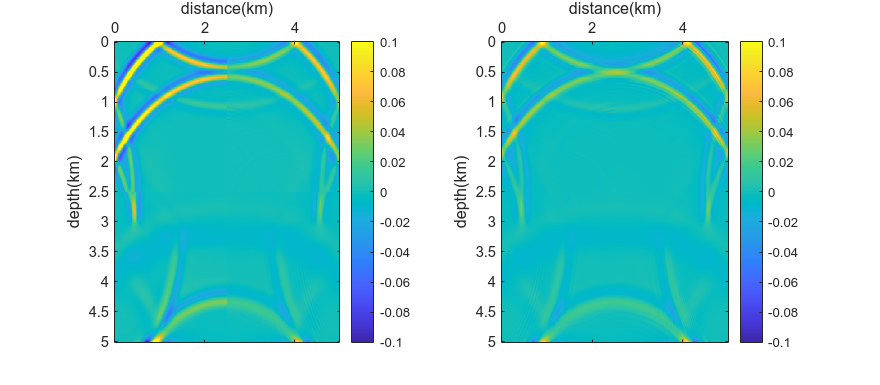

% figure('Position',[400 400 800 800])
% clip=0.1;
% for i = 1:nt_small
%     if rem(i,5)==0
%         subplot(2,2,1)
%         imagesc(real(squeeze(p00(:,:,i))))
%         colorbar
%         axis equal
%         axis tight
%         clim([-clip clip]) % for 'ricker' source
%         title(['No attenuation, p time (s) = ' , num2str((i-1)*dt)])
%         xlabel('x (m)'), ylabel('z (m)')   
% 
%         subplot(2,2,2)
%         imagesc(real(squeeze(p01(:,:,i))))
%         colorbar
%         axis equal
%         axis tight
%         clim([-clip clip]) % for 'ricker' source
%         title(['Only dissipitation, p time (s) = ' , num2str((i-1)*dt)])
%         xlabel('x (m)'), ylabel('z (m)')   
% 
%         subplot(2,2,3)
%         imagesc(real(squeeze(p10(:,:,i))))
%         colorbar
%         axis equal
%         axis tight
%         clim([-clip clip]) % for 'ricker' source
%         title(['Only dispersion, p time (s) = ' , num2str((i-1)*dt)])
%         xlabel('x (m)'), ylabel('z (m)')   
% 
%         subplot(2,2,4)
%         imagesc(real(squeeze(p11(:,:,i))))
%         colorbar
%         axis equal
%         axis tight
%         clim([-clip clip]) % for 'ricker' source
%         title(['Both, p time (s) = ' , num2str((i-1)*dt)])
%         xlabel('x (m)'), ylabel('z (m)')   
%         pause(0.01)
% 
%     end
% end

% figure('Position',[400 400 800 800])
% clip2=200;
% 
% 
% kx = 2*pi*(-nx/2:nx/2-1) / (h*nx);   % kx in rad/m
% kz = 2*pi*(-nz/2:nz/2-1) / (h*nz);   % kz in rad/m
% 
% 
% for i = 1:nt_small
%     if rem(i,50/t_interval)==0
%         p00_k=abs(fftshift(fft(fft(real(p00(:,:,i)),[],1),[],2)));
%         p01_k=abs(fftshift(fft(fft(real(p01(:,:,i)),[],1),[],2)));
%         p10_k=abs(fftshift(fft(fft(real(p10(:,:,i)),[],1),[],2)));
%         p11_k=abs(fftshift(fft(fft(real(p11(:,:,i)),[],1),[],2)));
%         subplot(2,2,1)
%         imagesc(kx, kz, p00_k(:,:)); 
%         colorbar
%         axis equal
%         axis tight
%         clim([-clip2 clip2]) 
%         title(['No attenuation, time (s) = ' , num2str((i-1)*dt)])
%         xlabel('k_x (rad/m)'); ylabel('k_z (rad/m)');
% 
%         subplot(2,2,2)
%         imagesc(kx, kz, p01_k(:,:)); 
%         colorbar
%         axis equal
%         axis tight
%         clim([-clip2 clip2]) 
%         title(['Only dissipitation, time (s) = ' , num2str((i-1)*dt)])
%         xlabel('k_x (rad/m)'); ylabel('k_z (rad/m)');
% 
%         subplot(2,2,3)
%         imagesc(kx, kz, p10_k(:,:)); 
%         colorbar
%         axis equal
%         axis tight
%         clim([-clip2 clip2]) 
%         title(['Only dispersion, time (s) = ' , num2str((i-1)*dt)])
%         xlabel('k_x (rad/m)'); ylabel('k_z (rad/m)');
% 
%         subplot(2,2,4)
%         imagesc(kx, kz, p11_k(:,:)); 
%         colorbar
%         axis equal
%         axis tight
%         clim([-clip2 clip2]) 
%         title(['Both, time (s) = ' , num2str((i-1)*dt)])
%         xlabel('k_x (rad/m)'); ylabel('k_z (rad/m)');
%         pause(0.1)
%         % frame = getframe(gcf);        % 获取当前图像帧
%         % writeVideo(v, frame);         % 写入视频
%     end
% end

x = (0:nx-1)*h/1000;
z = (0:nz-1)*h/1000;
figure('Position', [400 400 800 350]);
clip=0.1;
for i = 1:nt_small
    if rem(i,50/t_interval)==0
        combined=squeeze(p00(:,:,i));
        combined(nz/2:nz,1:nx/2)=p10(nz/2:nz,1:nx/2,i); %dispersion
        combined(1:nz/2,nx/2:nx)=p01(1:nz/2,nx/2:nx,i); %dissipation
        combined(nz/2:nz,nx/2:nx)=p11(nz/2:nz,nx/2:nx,i);
        subplot(1,2,1)
        imagesc(x,z,real(combined),[-clip,clip]) ;
        xlabel('distance(km)')
        ylabel('depth(km)')
        set(gca,'xaxisLocation','top')
        colorbar
        subplot(1,2,2)
        combined2=squeeze(p11(:,:,i)); % smooth in wavenumber domain
        combined2(:,nx/2:nx)=p11_fct(:,nx/2:nx,i); % smooth by FCT
        pause(0.01);
        imagesc(x,z,real(combined2),[-clip,clip]) ;
        xlabel('distance(km)')
        ylabel('depth(km)')
        set(gca,'xaxisLocation','top')
        colorbar
    end
end

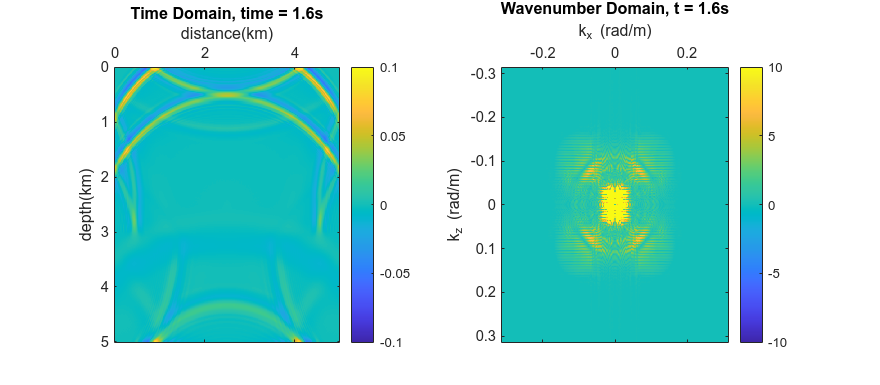


x = (0:nx-1)*h/1000;
z = (0:nz-1)*h/1000;
figure('Position', [400 400 800 350]);
clip=0.1;
clip2=10;
for i = 1:nt_small
    if rem(i,20/t_interval)==0
        subplot(1,2,1)
        imagesc(x,z,real(p11_fct(:,:,i)),[-clip,clip]) ;
        xlabel('distance(km)')
        ylabel('depth(km)')
        set(gca,'xaxisLocation','top')
        title(['Time Domain, time = ' , num2str(i*t_interval*dt),'s'])
        colorbar
        subplot(1,2,2)
        imagesc(kx, kz,abs(fftshift(fft(fft(real(p11_fct(:,:,i)),[],1),[],2))),[-clip2,clip2]) ;
        xlabel('k_x (rad/m)'); ylabel('k_z (rad/m)');set(gca,'xaxisLocation','top')
        title(['Wavenumber Domain, t = ', num2str(i*t_interval*dt),'s'])
        colorbar
        pause(0.01);
        % frame = getframe(gcf);        % 获取当前图像帧
        % writeVideo(v, frame);         % 写入视频
    end
end

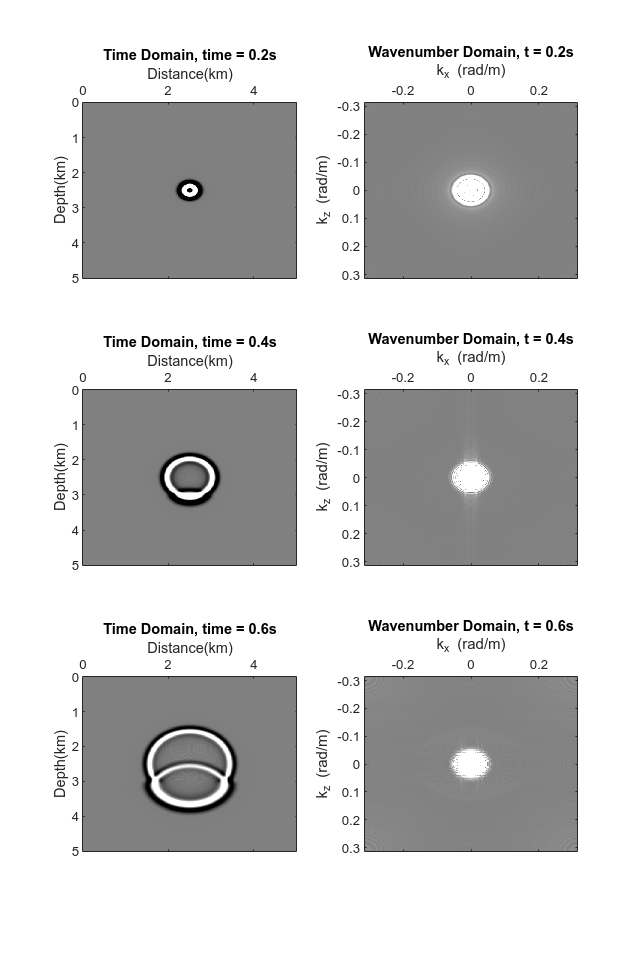

figure('Position', [400 400 800 1200]);
i=5;
subplot(3,2,1)
imagesc(x,z,real(p11_no_smooth(:,:,i)),[-clip,clip]) ;
xlabel('Distance(km)')
ylabel('Depth(km)')
set(gca,'xaxisLocation','top')
title(['Time Domain, time = ' , num2str(i*t_interval*dt),'s'])
% colorbar
subplot(3,2,2)
imagesc(kx, kz,abs(fftshift(fft(fft(real(p11_no_smooth(:,:,i)),[],1),[],2))),[-clip2,clip2]) ;
xlabel('k_x (rad/m)'); ylabel('k_z (rad/m)');set(gca,'xaxisLocation','top')
title(['Wavenumber Domain, t = ', num2str(i*t_interval*dt),'s'])
% colorbar

i=10;
subplot(3,2,3)
imagesc(x,z,real(p11_no_smooth(:,:,i)),[-clip,clip]) ;
xlabel('Distance(km)')
ylabel('Depth(km)')
set(gca,'xaxisLocation','top')
title(['Time Domain, time = ' , num2str(i*t_interval*dt),'s'])
% colorbar;
subplot(3,2,4)
imagesc(kx, kz,abs(fftshift(fft(fft(real(p11_no_smooth(:,:,i)),[],1),[],2))),[-clip2,clip2]) ;
xlabel('k_x (rad/m)'); ylabel('k_z (rad/m)');set(gca,'xaxisLocation','top')
title(['Wavenumber Domain, t = ', num2str(i*t_interval*dt),'s'])
% colorbar

i=15;
subplot(3,2,5)
imagesc(x,z,real(p11_no_smooth(:,:,i)),[-clip,clip]) ;
xlabel('Distance(km)')
ylabel('Depth(km)')
set(gca,'xaxisLocation','top')
title(['Time Domain, time = ' , num2str(i*t_interval*dt),'s'])
% colorbar
subplot(3,2,6)
imagesc(kx, kz,abs(fftshift(fft(fft(real(p11_no_smooth(:,:,i)),[],1),[],2))),[-clip2,clip2]) ;
xlabel('k_x (rad/m)'); ylabel('k_z (rad/m)');set(gca,'xaxisLocation','top')
title(['Wavenumber Domain, t = ', num2str(i*t_interval*dt),'s'])
% colorbar;
colormap('gray');

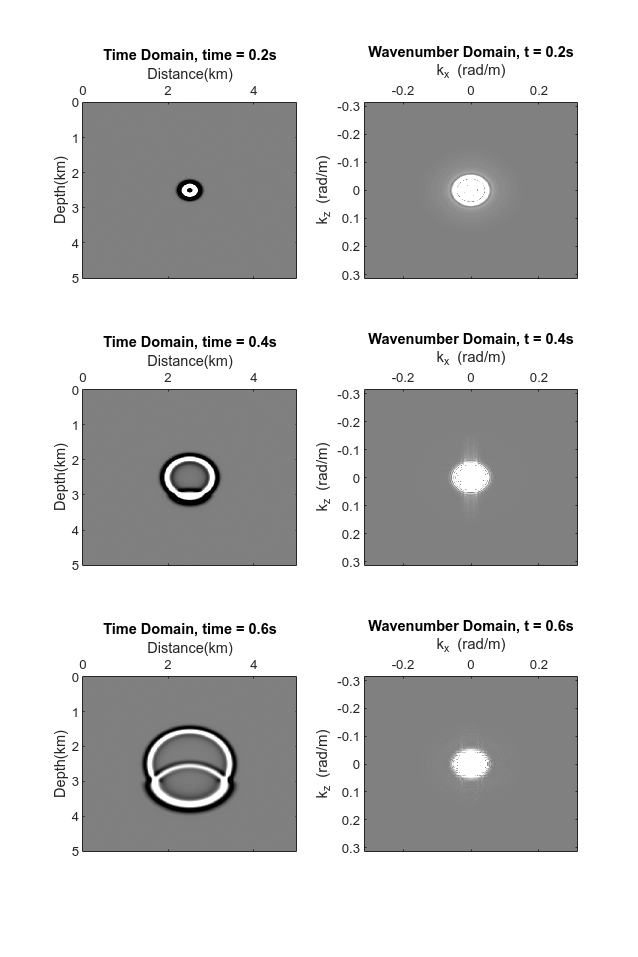


% i=30;
% subplot(4,2,7)
% imagesc(x,z,real(p11_no_smooth(:,:,i)),[-clip,clip]) ;
% xlabel('Distance(km)')
% ylabel('Depth(km)')
% set(gca,'xaxisLocation','top')
% title(['Time Domain, time = ' , num2str(i*t_interval*dt),'s'])
% % colorbar
% subplot(4,2,8)
% imagesc(kx, kz,abs(fftshift(fft(fft(real(p11_no_smooth(:,:,i)),[],1),[],2))),[-clip2,clip2]) ;
% xlabel('k_x (rad/m)'); ylabel('k_z (rad/m)');set(gca,'xaxisLocation','top')
% title(['Wavenumber Domain, t = ', num2str(i*t_interval*dt),'s'])
% colorbar; colormap('gray');


figure('Position', [400 400 800 1200]);
i=5;
subplot(3,2,1)
imagesc(x,z,real(p11(:,:,i)),[-clip,clip]) ;
xlabel('Distance(km)')
ylabel('Depth(km)')
set(gca,'xaxisLocation','top')
title(['Time Domain, time = ' , num2str(i*t_interval*dt),'s'])
% colorbar
subplot(3,2,2)
imagesc(kx, kz,abs(fftshift(fft(fft(real(p11(:,:,i)),[],1),[],2))),[-clip2,clip2]) ;
xlabel('k_x (rad/m)'); ylabel('k_z (rad/m)');set(gca,'xaxisLocation','top')
title(['Wavenumber Domain, t = ', num2str(i*t_interval*dt),'s'])
% colorbar

i=10;
subplot(3,2,3)
imagesc(x,z,real(p11(:,:,i)),[-clip,clip]) ;
xlabel('Distance(km)')
ylabel('Depth(km)')
set(gca,'xaxisLocation','top')
title(['Time Domain, time = ' , num2str(i*t_interval*dt),'s'])
% colorbar;
subplot(3,2,4)
imagesc(kx, kz,abs(fftshift(fft(fft(real(p11(:,:,i)),[],1),[],2))),[-clip2,clip2]) ;
xlabel('k_x (rad/m)'); ylabel('k_z (rad/m)');set(gca,'xaxisLocation','top')
title(['Wavenumber Domain, t = ', num2str(i*t_interval*dt),'s'])
% colorbar

i=15;
subplot(3,2,5)
imagesc(x,z,real(p11(:,:,i)),[-clip,clip]) ;
xlabel('Distance(km)')
ylabel('Depth(km)')
set(gca,'xaxisLocation','top')
title(['Time Domain, time = ' , num2str(i*t_interval*dt),'s'])
% colorbar
subplot(3,2,6)
imagesc(kx, kz,abs(fftshift(fft(fft(real(p11(:,:,i)),[],1),[],2))),[-clip2,clip2]) ;
xlabel('k_x (rad/m)'); ylabel('k_z (rad/m)');set(gca,'xaxisLocation','top')
title(['Wavenumber Domain, t = ', num2str(i*t_interval*dt),'s'])
% colorbar;
colormap('gray');

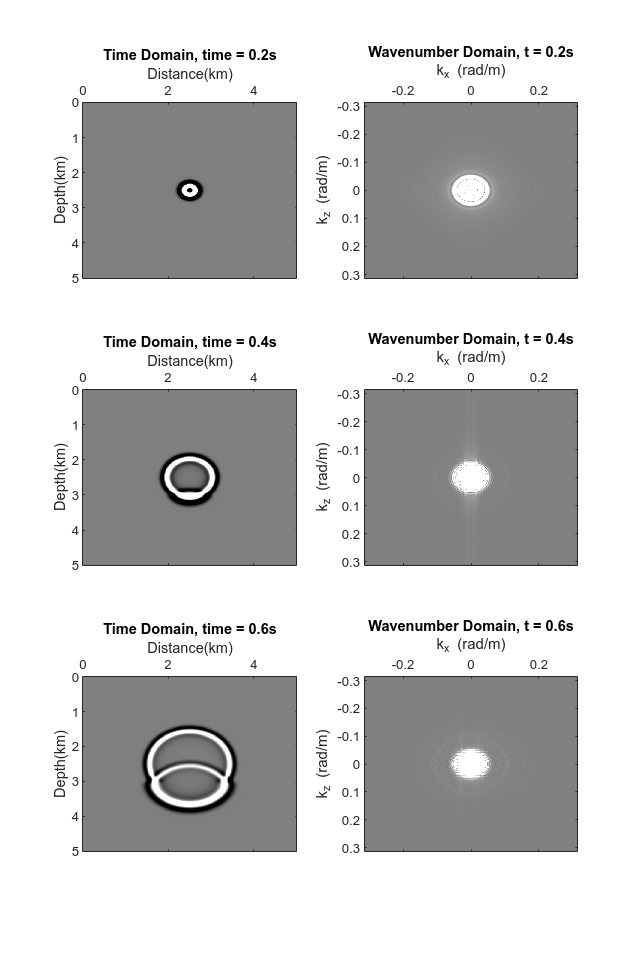


figure('Position', [400 400 800 1200]);
i=5;
subplot(3,2,1)
imagesc(x,z,real(p11_fct(:,:,i)),[-clip,clip]) ;
xlabel('Distance(km)')
ylabel('Depth(km)')
set(gca,'xaxisLocation','top')
title(['Time Domain, time = ' , num2str(i*t_interval*dt),'s'])
% colorbar
subplot(3,2,2)
imagesc(kx, kz,abs(fftshift(fft(fft(real(p11_fct(:,:,i)),[],1),[],2))),[-clip2,clip2]) ;
xlabel('k_x (rad/m)'); ylabel('k_z (rad/m)');set(gca,'xaxisLocation','top')
title(['Wavenumber Domain, t = ', num2str(i*t_interval*dt),'s'])
% colorbar

i=10;
subplot(3,2,3)
imagesc(x,z,real(p11_fct(:,:,i)),[-clip,clip]) ;
xlabel('Distance(km)')
ylabel('Depth(km)')
set(gca,'xaxisLocation','top')
title(['Time Domain, time = ' , num2str(i*t_interval*dt),'s'])
% colorbar;
subplot(3,2,4)
imagesc(kx, kz,abs(fftshift(fft(fft(real(p11_fct(:,:,i)),[],1),[],2))),[-clip2,clip2]) ;
xlabel('k_x (rad/m)'); ylabel('k_z (rad/m)');set(gca,'xaxisLocation','top')
title(['Wavenumber Domain, t = ', num2str(i*t_interval*dt),'s'])
% colorbar

i=15;
subplot(3,2,5)
imagesc(x,z,real(p11_fct(:,:,i)),[-clip,clip]) ;
xlabel('Distance(km)')
ylabel('Depth(km)')
set(gca,'xaxisLocation','top')
title(['Time Domain, time = ' , num2str(i*t_interval*dt),'s'])
% colorbar
subplot(3,2,6)
imagesc(kx, kz,abs(fftshift(fft(fft(real(p11_fct(:,:,i)),[],1),[],2))),[-clip2,clip2]) ;
xlabel('k_x (rad/m)'); ylabel('k_z (rad/m)');set(gca,'xaxisLocation','top')
title(['Wavenumber Domain, t = ', num2str(i*t_interval*dt),'s'])
% colorbar;
colormap('gray');

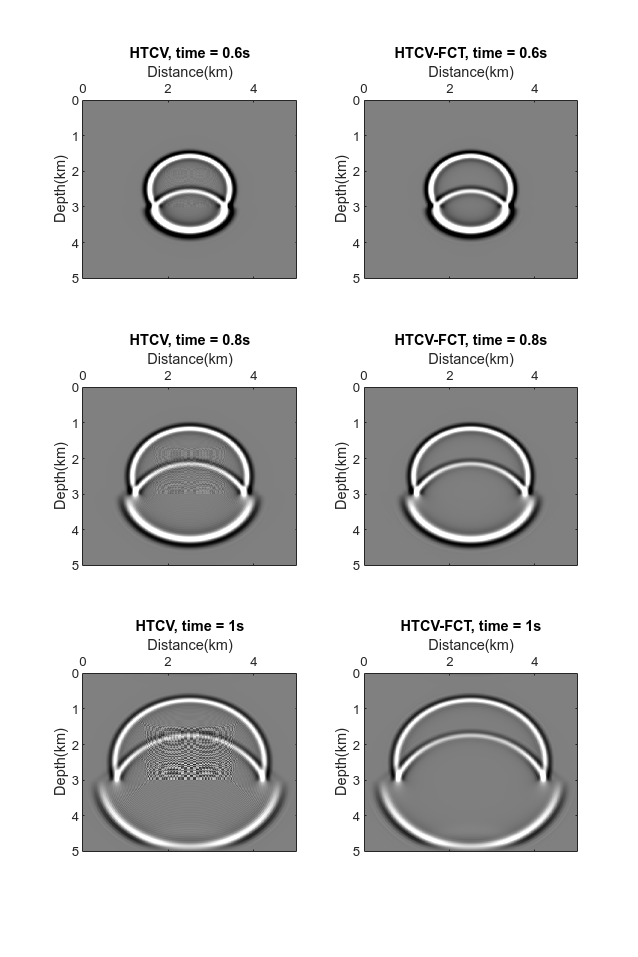

clip=0.3
figure('Position', [400 400 800 1200]);
i=10;
subplot(3,2,1)
imagesc(x,z,real(p11_no_smooth(:,:,i)),[-clip,clip]) ;
xlabel('Distance(km)')
ylabel('Depth(km)')
set(gca,'xaxisLocation','top')
title(['HTCV, time = ' , num2str(i*t_interval*dt),'s'])
% colorbar
subplot(3,2,2)
imagesc(x,z,real(p11_fct(:,:,i)),[-clip,clip]) ;
xlabel('Distance(km)')
ylabel('Depth(km)')
set(gca,'xaxisLocation','top')
title(['HTCV-FCT, time = ' , num2str(i*t_interval*dt),'s'])
% colorbar

i=20;
subplot(3,2,3)
imagesc(x,z,real(p11_no_smooth(:,:,i)),[-clip,clip]) ;
xlabel('Distance(km)')
ylabel('Depth(km)')
set(gca,'xaxisLocation','top')
title(['HTCV, time = ' , num2str(i*t_interval*dt),'s'])
% colorbar
subplot(3,2,4)
imagesc(x,z,real(p11_fct(:,:,i)),[-clip,clip]) ;
xlabel('Distance(km)')
ylabel('Depth(km)')
set(gca,'xaxisLocation','top')
title(['HTCV-FCT, time = ' , num2str(i*t_interval*dt),'s'])
% colorbar

i=30;
subplot(3,2,5)
imagesc(x,z,real(p11_no_smooth(:,:,i)),[-clip,clip]) ;
xlabel('Distance(km)')
ylabel('Depth(km)')
set(gca,'xaxisLocation','top')
title(['HTCV, time = ' , num2str(i*t_interval*dt),'s'])
% colorbar
subplot(3,2,6)
imagesc(x,z,real(p11_fct(:,:,i)),[-clip,clip]) ;
xlabel('Distance(km)')
ylabel('Depth(km)')
set(gca,'xaxisLocation','top')
title(['HTCV-FCT, time = ' , num2str(i*t_interval*dt),'s'])
% colorbar;
colormap('gray');

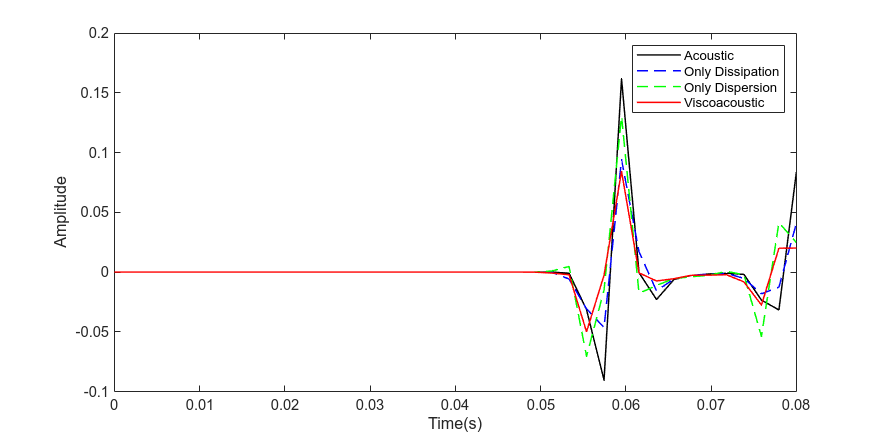


figure('Position',[400 400 800 400])
location_x = 100;
location_z = 100;
plot(linspace(0,nt_small*dt,nt_small), squeeze(real(p00(location_z,location_x,:))), '-','Color', 'k','LineWidth',1); hold  on;
plot(linspace(0,nt_small*dt,nt_small), squeeze(real(p01(location_z,location_x,:))), '--','Color', 'blue','LineWidth',1); hold  on;
plot(linspace(0,nt_small*dt,nt_small), squeeze(real(p10(location_z,location_x,:))), '--','Color', 'green','LineWidth',1); hold  on;
plot(linspace(0,nt_small*dt,nt_small), squeeze(real(p11(location_z,location_x,:))),'Color', 'red','LineWidth',1);
xlabel('Time(s)')
ylabel('Amplitude')
% set(gca, 'YDir', 'reverse');
legend('Acoustic','Only Dissipation', 'Only Dispersion', 'Viscoacoustic')

## **For 2 Step AC FD modeling**


$$\rho a = \nabla p$$



$$\ddot p = \kappa \nabla a$$


staggered grids

1         --------     --------

        |                |            |

 $\frac{1}{2}$   $a_{z}$ --------     --------

        |                |            |

        $p_{ii}$ -------- $a_{x}$--------

    0                 $\frac{1}{2}$             1

matrix form 


$$M \left [ \matrix {(a^n_z)_{i+1/2,j} \cr (a^n_x)_{i,j+1/2} \cr  (\ddot p^n)__{i,j}} \right ] = \left [ \matrix{0 & 0 & \partial^f_z \cr 0 & 0 & \partial^f_x \cr \partial_z^b & \partial_x^b & 0} \right ] \left[ \matrix{(a_z^n)_{i+1/2,j} \cr (a_x^n)_{i,j+1/2} \cr (p^n)_{i,j}} \right ]$$


$M=\left [ \matrix{diag(\rho) & 0 \cr 0 & \kappa ^{-1}} \right ]$, $N=M^{-1}=\left [ \matrix{diag(b) & 0 \cr 0 & \kappa} \right ]$, $D=\left [ \matrix{0 & 0 & \partial^f_z \cr 0 & 0 & \partial^f_x \cr \partial_z^b & \partial_x^b & 0} \right ]$.

Fourier transform


$$\left [ \matrix{\rho & 0 & 0 \cr 0 & \rho & 0 \cr 0 &  0 & -\frac{\omega^2}{\kappa }} \right ] \left [ \matrix {(a^n_z)_{i+1/2,j} \cr (a^n_x)_{i,j+1/2} \cr  ( p^n)__{i,j}} \right ] = \left [ \matrix{0 & 0 & \partial^f_z \cr 0 & 0 & \partial^f_x \cr \partial_z^b & \partial_x^b & 0} \right ] \left[ \matrix{(a_z^n)_{i+1/2,j} \cr (a_x^n)_{i,j+1/2} \cr (p^n)_{i,j}} \right ]$$


Kolsky-Futterman model: $c(\omega)=c(\omega_0)\left[1+\frac{1}{\pi Q}\ln\frac{\omega}{\omega_0}-\frac{i\text{sgn}(\omega)}{2Q}\right]$, or $\frac{1}{c(\omega)^2}=\frac{1}{c(\omega_0)^2}\left[1-\frac{2}{\pi Q}\ln\frac{\omega}{\omega_0}+\frac{i\text{sgn}(\omega)}{Q}\right]$ 


$$\left [ \matrix{\rho & 0 & 0 \cr 0 & \rho & 0 \cr 0 &  0 & -\frac{\omega^2}{\kappa_0 }\left[1-\frac{2}{\pi Q}\ln\frac{\omega}{\omega_0}+\frac{i\text{sgn}(\omega)}{Q}\right]} \right ] \left [ \matrix {(a^n_z)_{i+1/2,j} \cr (a^n_x)_{i,j+1/2} \cr  (p^n)__{i,j}} \right ] = \left [ \matrix{0 & 0 & \partial^f_z \cr 0 & 0 & \partial^f_x \cr \partial_z^b & \partial_x^b & 0} \right ] \left[ \matrix{(a_z^n)_{i+1/2,j} \cr (a_x^n)_{i,j+1/2} \cr (p^n)_{i,j}} \right ]$$


Use approximation: $\omega^2\ln\frac{\omega}{\omega_0}\approx a\omega^2+b\omega+d$, where $a=5.7356, b=-762.1606, d=4.6054\times10^4$


$$\left [ \matrix{\rho & 0 & 0 \cr 0 & \rho & 0 \cr 0 &  0 & -\frac{1}{\kappa_0 }\left[ \left( 1 -\frac{2a}{\pi Q} -\frac{i}{Q}  \right)\omega^2-\frac{2b}{\pi Q}\omega - \frac{2d}{\pi Q} \right] } \right ] \left [ \matrix {(a^n_z)_{i+1/2,j} \cr (a^n_x)_{i,j+1/2} \cr  (p^n)__{i,j}} \right ] = \left [ \matrix{0 & 0 & \partial^f_z \cr 0 & 0 & \partial^f_x \cr \partial_z^b & \partial_x^b & 0} \right ] \left[ \matrix{(a_z^n)_{i+1/2,j} \cr (a_x^n)_{i,j+1/2} \cr (p^n)_{i,j}} \right ]$$


Inverse Fourier Transform


$$\left [ \matrix{\rho & 0 & 0 \cr 0 & \rho & 0 \cr 0 &  0 & \frac{1}{\kappa_0 }\left[ \left( 1 -\frac{2a}{\pi Q} -\frac{i}{Q}  \right)\partial_{tt}-\frac{2bi}{\pi Q}\partial_t + \frac{2d}{\pi Q} \right] } \right ] \left [ \matrix {(a^n_z)_{i+1/2,j} \cr (a^n_x)_{i,j+1/2} \cr  ( p^n)__{i,j}} \right ] = \left [ \matrix{0 & 0 & \partial^f_z \cr 0 & 0 & \partial^f_x \cr \partial_z^b & \partial_x^b & 0} \right ] \left[ \matrix{(a_z^n)_{i+1/2,j} \cr (a_x^n)_{i,j+1/2} \cr (p^n)_{i,j}} \right ]$$


$C1=1-\frac{2a}{\pi Q} - \frac{i}{Q} - \frac{bi}{\pi Q}\Delta t$, $C2=2(1-\frac{2a}{\pi Q} - \frac{i}{Q}-\frac{d}{\pi Q}\Delta t^2)$, $C3=- \left(1 - \frac{2a}{\pi Q} - \frac{i}{Q} + \frac{bi}{\pi Q} \Delta t \right )$

Time marching


$$\left [ \matrix{(a^n_z)_{i+1/2,j} \cr (a^n_x)_{i,j+1/2} \cr  (C_1p^_{n+1})_{i,j}} \right ] = \left [ \matrix{0 \cr 0 \cr C_2p^n + C_3p^{n-1}} \right ] + M^{-1} \left [ \matrix{\partial_z^f (p^n)_{i,j} \cr \partial _x^f (p^n)_{i,j} \cr \Delta t^2(\partial_z^b (a_z^n)_{i+1/2,j} + \partial_x^b (a_x^n)_{i,j+1/2})} \right] + M^{-1}f \Delta t^2$$


integration by parts:

$\int a^HM\partial_tudt = a^HMu|_{t=0}^T - \int(\partial_ta^H)Mudt$, $a(t=0)=0$ and $a(t=T)=0$(final condation)


$$\int a^HM\partial_tudt = - \int (\partial_ta^H)Mudt$$



$$\int a^HM\partial_{tt}udt = a^HM\partial_tu|_{t=0}^T - \int(\partial_ta^H)M\partial_tudt = a^HM\partial_tu|_{t=0}^T - (\partial_ta^H)Mu|_{t=0}^T + \int(\partial_{tt}a^H)Mudt = \int(\partial_{tt}a^H)Mudt$$


forward $p$: $\frac{1}{{\kappa_0 }}\left[ \left( 1 -\frac{2a}{\pi Q} -\frac{i}{Q}  \right)\partial_{tt}-\frac{2bi}{\pi Q}\partial_t + \frac{2d}{\pi Q} \right]$

adjoint $p^a$: $\frac{1}{{\kappa_0 }}\left[ \left( 1 -\frac{2a}{\pi Q} +\frac{i}{Q}  \right)\partial_{tt}-\frac{2bi}{\pi Q}\partial_t + \frac{2d}{\pi Q} \right]$ (for adjoint wave, consider transpose and conjugate, according to defination of inner product. Both adjoint wave and kernal should consider this)

For the inverse time direction of $\partial_t a$, in code, it leads to:

adjoint $p^a$: $\frac{1}{{\kappa_0 }}\left[ \left( 1 -\frac{2a}{\pi Q} +\frac{i}{Q}  \right)\partial_{tt}+\frac{2bi}{\pi Q}\partial_t + \frac{2d}{\pi Q} \right]$

Also, for spatial derivatives:


$$\int a^HDudx^3 = -\int (D^Ha)^Hudx^3$$


Therefore, $A^Ha= M^Ha+D^Ha=M^Ha-D^*a$, where $M^H=
\matrix{\left [ \matrix{\rho & 0 & 0 \cr 0 & \rho & 0 \cr 0 &  0 & \frac{1}{\kappa_0 }\left[ \left( 1 -\frac{2a}{\pi Q} +\frac{i}{Q}  \right)\partial_{tt}+\frac{2bi}{\pi Q}\partial_t + \frac{2d}{\pi Q} \right] } \right ]}$, $D^*=conjugate(D)$. 

There are 3 steps which need to consider + or -.

1. conjugate for inner product

2. intergration by parts

3. time direction for finite difference. $\partial_tu=\frac{u_{t+1}-u_{t}}{\Delta t}$, $\partial_ta=\frac{a_{t}-a_{t+1}}{\Delta t}=-\frac{a_{t+1}-a_{t}}{\Delta t}$

Gradient:

Since the ajoint wave is complex number, we consider conjugate wave: $a \rightarrow \overline a$


$$K_m<a|Au>=K_m<a| Mu +Du>$$


For $\rho$:

$g_{\rho}= a^{ajoint,H}a= a^{ajoint,H}b\nabla p$, note: here $a$ is acceleration.

For $\kappa$:


$$g_{\kappa}=p^{ajoint,H}(-\kappa ^{-2})\left[ \left( 1 -\frac{2a}{\pi Q} -\frac{i}{Q}  \right)\partial_{tt}+\frac{2bi}{\pi Q}\partial_t + \frac{2d}{\pi Q} \right]p =  p^{ajoint,H}(-\kappa^{-1})\nabla a$$


For $Q$:


$$g_Q=\overline p^{ajoint}\frac{1}{\kappa_0} \left [ (\frac{2a}{\pi Q^2}+\frac{i}{Q^2}) \partial_{tt} - \frac{2b}{\pi Q^2}\partial_t - \frac{2d}{\pi Q^2} \right ] p$$


Derivation of Largrange method

inner product:


$$<a|Mu>=\int a^H M u dt$$


target function:

$C=\frac{1}{2}|| Ru - d||^2_2=\frac{1}{2}<Ru-d|Ru-d>
$. Here we can only consider it is real number! 

Even consider complex number, the derivative can cancel the imaginary parts.

Largrange function


$$L(u,a,m)=C+<a|M(m)u-Du>$$


Gradient:

$\frac{\partial L}{\partial m}= \frac{\partial L}{\partial u} \frac{\partial u}{\partial m}+ \frac{\partial L}{\partial a} \frac{\partial a}{\partial m} + \frac{\partial L}{\partial m}$.

Let $\frac{\partial L}{\partial u}=0$ and $\frac{\partial L}{\partial a}=0$:

$\frac{\partial L}{\partial u}=\frac{\partial C}{\partial u}+\frac{\partial<a|Mu-Du>}{\partial u}=0$,  $\frac{\partial<a|Mu-Du>}{\partial u}=-\frac{\partial C}{\partial u}$ .  $<a|Mu-Du>=<M^Ha-D^Ha|u>$

$\frac{\partial}{\partial u}\int (M^H a)^H udt \rightarrow \int (M^Ha)^H dt$, $\frac{\partial C}{\partial u}=Ru -d$

$M^H a = -(Ru-d)$ or $Ma^H=-(Ru-d)^H$

$\frac{\partial L}{\partial a} = \frac{\partial C}{\partial a}+ \frac{\partial}{\partial a}<a|Mu-Du>=0+Mu-du=0$, which satisfy wave equation.


$$\frac{\partial L}{\partial m}=\frac{\partial}{\partial m}<a|Mu-Du>= \int a^H \frac{\partial M}{\partial m}udt$$


in acoustic case, $\frac{\partial M}{\partial m} = \matrix {\left[ \matrix{\frac{\partial \rho}{\partial m} & 0 & 0 \cr 0 & \frac{\partial \rho}{\partial m} &  0 \cr 0 & 0 & \frac{\partial\kappa^{-1}}{\partial m}} \right ]}$


$$\frac{1}{\rho (\mathrm{x})v_0^2(\mathrm{x})} \left[ C_1 \frac{\partial^2p(\mathrm{x,t})}{\partial t^2} -iC_2 \frac{\partial p(\mathrm{x,t})}{\partial t} +C_3p(\mathrm{x,t}) \right] -C_4 \sqrt{-\nabla^2} \frac{\partial p(\mathrm{x,t})}{\partial t} = \nabla \cdot \left[\frac{1}{\rho(\mathrm{x})} \nabla p(\mathrm{x,t}) \right]$$



$$\omega^2 \rm{ln}\frac{\omega}{\omega_0}\approx a \omega^2+b\omega+d$$
 

## Flux-Corrected Transport(FCT) method

1. Obtain the $P_{i,j,k}^{n+1}$

2. Compute diffusive fluxes at time step n:


$$Q_{x_{i+1/2,j,k}}^n=\eta_1[(P_{i+1,j,k}^n-P_{i,j,k}^n)-(P_{i+1,j,k}^{n-1}-P_{i,j,k}^{n-1})] \\
Q_{y_{i,j+1/2,k}}^n=\eta_1[(P_{i,j+1,k}^n-P_{i,j,k}^n)-(P_{i,j+1,k}^{n-1}-P_{i,j,k}^{n-1})] \\
Q_{z_{i,j,k+1/2}}^n=\eta_1[(P_{i,j,k+1}^n-P_{i,j,k}^n)-(P_{i,j,k+1}^{n-1}-P_{i,j,k}^{n-1})] 
$$


where $0\leq \eta_1 \leq 1$. 0.04 and 0.01 are used order and 4th order in original paper

3. Compute diffusive fluxes at time step n+1:


$$\overline{Q}_{x_{i+1/2,j,k}}^{n+1}=\eta_2[(P_{i+1,j,k}^{n+1}-P_{i,j,k}^{n+1})-(P_{i+1,j,k}^{n}-P_{i,j,k}^{n})] \\
\overline{Q}_{y_{i,j+1/2,k}}^{n+1}=\eta_2[(P_{i,j+1,k}^{n+1}-P_{i,j,k}^{n+1})-(P_{i,j+1,k}^{n}-P_{i,j,k}^{n})] \\
\overline{Q}_{z_{i,j,k+1/2}}^{n+1}=\eta_2[(P_{i,j,k+1}^{n+1}-P_{i,j,k}^{n+1})-(P_{i,j,k+1}^{n}-P_{i,j,k}^{n})] 
$$


$\eta_2$ is 10-15% larger than $\eta_1$, 0.045 and 0.012 for 2nd order and 4th order

4. Modify the solution P by Qx, Qy and Qz in step 2. This process smooths the solution (cause some loss of amplitude) and eliminates the dispersive ripples:


$$\overline{P}_{i,j,k}^{n+1} = P_{i,j,k}^{n+1} + (Q_{x_{i+1/2,j,k}}^n-Q_{x_{i-1/2,j,k}}^n) + (Q_{y_{i,j+1/2,k}}^n-Q_{y_{i,j-1/2,k}}^n) + (Q_{z_{i,j,k+1/2}}^n-Q_{z_{i,j,k-1/2}}^n)$$


5. Compute diffusive fluxes with $\overline{P}^{n+1}$ and $P^n$:


$$X_{i+1/2,j,k} = (\overline{P}_{i+1,j,k}^{n+1}-P_{i+1,j,k}^{n}) - (\overline{P}_{i,j,k}^{n+1}-P_{i,j,k}^{n}) \\
Y_{i+1/2,j,k} = (\overline{P}_{i,j+1,k}^{n+1}-P_{i,j+1,k}^{n}) - (\overline{P}_{i,j,k}^{n+1}-P_{i,j,k}^{n}) \\
Z_{i+1/2,j,k} = (\overline{P}_{i,j,k+1}^{n+1}-P_{i,j,k+1}^{n}) - (\overline{P}_{i,j,k}^{n+1}-P_{i,j,k}^{n}) $$


6. Antidiffuses the sllution as follow:


$$P_{i,j,k}^{n+1} = \overline P_{i,j,k}^{n+1} - (X_{i+1/2,j,k}^c-X_{i-1/2,j,k}^c) - (Y_{i,j+1/2,k}^c-Y_{i,j-1/2,k}^c) - (Z_{i,j,k+1/2}^c-Z_{i,j,k-1/2}^c)$$


where


$$X_{i+1/2,j,k}^c = S_x max\{0, min [\cdot S_xX_{i-1/2,j,k}, abs(\overline Q_{x_{i+1/2,j,k}}^{n+1}), S_xX_{i+3/2,j,k}]\} \\
Y_{i,j+1/2,k}^c = S_y max\{0, min [\cdot S_yY_{i,j-1/2,k}, abs(\overline Q_{y_{i,j+1/2,k}}^{n+1}), S_yY_{i,j+3/2,k}]\}  \\
Z_{i,j+1/2,k}^c = S_z max\{0, min [\cdot S_zZ_{i,j,k-1/2}, abs(\overline Q_{z_{i,j,k+1/2}}^{n+1}), S_zZ_{i,j,k+3/2}]\}$$



$$S_x = sign \{\overline Q_{x_{i+1/2,j,k}}^{n+1} \} \\
S_y = sign \{\overline Q_{y_{i,j+1/2,k}}^{n+1} \} \\
S_z = sign \{\overline Q_{z_{i,j,k+1/2}}^{n+1} \}$$


function [a_log_x, a_log_z, p_log]=modeling_AC(model,mode,spatial_grid,source,temporal_grid,space_grid,t_interval,smooth_method)
    
    %model
    vp=model{1};
    vs=model{2};
    rho=model{3};
    alpha=model{4};
    Q=model{5};
    mask=model{6};

    % mu = vs^2*rho;
    kappa = vp.^2.*rho;
    
    %spatial grid
    nz=spatial_grid{1};
    nx=spatial_grid{2};
    h=spatial_grid{3};
    
    %source term
    wl_hilbert=hilbert(source{1});
    src=wl_hilbert;
    % src = source{1};
    izs=source{2}; ixs=source{3};
    fp=source{4};
    
    %temporal grid
    nt=temporal_grid{1};
    dt=temporal_grid{2};
    

    %KF model
    if mode(1)~=0
        % a=5.7356; b=-762.1606; d=4.6054e4;
        a = 3.7801; b=-110.6870; d=1111.5;
        disp('Has Dispersion');
    else
        a=0.; b=0.; d=0.;
        disp('NO Dispersion');
    end
    if mode(2)~=0
        e=1; disp('Has Dissipation');
    else
        e=0; disp('NO Dissipation');
    end

    C1= (1 -2*a/pi/Q -e*1i/Q -b*1i/pi/Q*dt);
    C1=1./C1;
    C2= (1 -2*a/pi/Q -e*1i/Q              -d/pi/Q*dt*dt)*2;
    C3=-(1 -2*a/pi/Q -e*1i/Q +b*1i/pi/Q*dt);
    % C1= 1;
    % C2= 1;
    % C3= 1;
    
    %wavefields
    a_log_x = complex(zeros(nz,nx,nt/t_interval));
    a_log_z = complex(zeros(nz,nx,nt/t_interval));
    p_log=zeros(nz,nx,nt/t_interval);
    p=complex(zeros(nz,nx));
    % pnew=zeros(nz,nx);
    pold=complex(zeros(nz,nx));
    pnew=complex(zeros(nz,nx));
    pold2=complex(zeros(nz,nx));
    
    % acceleration_dx=complex(zeros(nz,nx));
    % acceleration_dz=complex(zeros(nz,nx));
    % E=complex(zeros(2,2,nz,nx)); 
    % sigma=complex(zeros(2,2,nz,nx));

    %auxiliary variables
    r=vp*dt; r2=r.*r;
        
    % %smoothing
    ismth_start=1;
    ismth=100;

    n_absorb = 40;
    absorbtion = 0.98;
    
    absorb = get_absorbing_bc(absorbtion, n_absorb, nx, nz);
    
    %Mur ABC
    % [c1,c2,c3,c4]=abc_coef(r,r2);
    rhoi = 1./rho;

    eta1 = 0.01;

    eta2 = 0.012;
    for it=1:nt
      
        %if(mod(it,100)==0) disp(it), end
        if(mod(it,100)==0)
            it,min(pnew(:,:),[],'all','includenan'),max(pnew(:,:),[],'all','includenan')
        end

        p(:,:) = p(:,:).*absorb(:,:);
        pold(:,:) = pold(:,:).*absorb(:,:);

        p(izs,ixs) = p(izs,ixs)+src(it);
        

        acceleration_dx = rhoi.*(D(0,1,p, space_grid,h));
        acceleration_dz = rhoi.*(D(1,1,p, space_grid,h));

        % acceleration_dz(izs,ixs) = acceleration_dz(izs,ixs)+src(it);

        pnew = C1.*(C2.*p + C3.*pold + dt^2.*kappa.*(D(0,-1,acceleration_dx,space_grid,h) ...
                                                   + D(1,-1,acceleration_dz,space_grid,h)));
        % pnew = 2*p - pold + dt^2.*kappa.*(D(0,-1,acceleration_dx,xp1, x, xm1, zp1, z, zm1, h) ...
        %                                            + D(1,-1,acceleration_dz,xp1, x, xm1, zp1, z, zm1, h));


        if mode(2)~=0
            if smooth_method == 1
                % if  it >= ismth_start
                % p = FCT_2D(p,pold,pold2,eta1,eta2,space_grid);
                pnew = complex(FCT_2D(real(pnew),real(p),real(pold),eta1,eta2,space_grid), ...
                               FCT_2D(imag(pnew),imag(p),imag(pold),eta1,eta2,space_grid));
                % end
            elseif smooth_method == 2
                if mod(it,ismth)==0
                pnew = fft_filter(pnew, mask);
                p = fft_filter(p, mask);
                end
            % elseif smooth_method == 0
            %     continue
            end
        end
        
        pold2 = pold;
        pold(:,:) = p(:,:) ;
        p(:,:)  = pnew(:,:) ;
        if(mod(it,t_interval)==0)
            p_log(:,:,it/t_interval)= pnew;
            a_log_x(:,:,it/t_interval)= acceleration_dx;
            a_log_z(:,:,it/t_interval)= acceleration_dz;
        end


    end

end

function U=modeling(model,mode,spatial_grid,source,temporal_grid)
    global xp1 x xm1 zp1 z zm1;
    %model
    c0=model{1};
    Q=model{2};
    
    %spatial grid
    nz=spatial_grid{1};
    nx=spatial_grid{2};
    h=spatial_grid{3};
    
    %source term
    src=hilbert(source{1});
    izs=source{2}; ixs=source{3};
    fp=source{4};
    
    %temporal grid
    nt=temporal_grid{1};
    dt=temporal_grid{2};
    
    %KF model
    if mode(1)~=0
        a=5.7356; b=-762.1606; d=4.6054e4;
        disp('Has Dispersion');
    else
        a=0.; b=0.; d=0.;
        disp('NO Dispersion');
    end
    if mode(2)~=0
        e=1; disp('Has Dissipation');
    else
        e=0; disp('NO Dissipation');
    end
    
    C1= (1 -2*a/pi/Q -e*1i/Q -b*1i/pi/Q*dt); C1=1./C1;
    C2= (1 -2*a/pi/Q -e*1i/Q              -d/pi/Q*dt*dt)*2;
    C3=-(1 -2*a/pi/Q -e*1i/Q +b*1i/pi/Q*dt);
    
    %wavefields
    U=complex(zeros(nz,nx,nt));
    
    %auxiliary variables
    r=c0*dt/h; r2=r.*r;
    lap=complex(zeros(nz,nx,1));
        
    %smoothing
    sigma=1;
    ismth_start=ceil(2/fp/dt);
    ismth=50;
    
%     %Mur ABC
%     [c1,c2,c3,c4]=abc_coef(r,r2);
% 
%     for it=2:nt-1
% 
%         %if(mod(it,100)==0) disp(it), end
%         if(mod(it,100)==0)
%             it,min(real(U(:,:,it)),[],'all','includenan'),max(real(U(:,:,it)),[],'all','includenan')
%         end
% 
%         %inject source
%         U(izs,ixs,it)=U(izs,ixs,it)+src(it);
% 
%         %laplace
%         ix=2:nx-1;
%         iz=2:nz-1;
%         lap(iz,ix,1) = U(iz+1,ix,it) +U(iz-1,ix,it) +U(iz,ix+1,it) +U(iz,ix-1,it) -4*U(iz,ix,it);
% 
%         %update wavefield
%         U(:,:,it+1) = C1*(C2*U(:,:,it) +C3*U(:,:,it-1) +r2*lap);
% 
%         %remove instabilities by smoothing
%         if mode(2)~=0
%         if it>=ismth_start
%         if mod(it,ismth)==0
%             U(:,:,it  )=complex(imgaussfilt(real(U(:,:,it  )),sigma), imgaussfilt(imag(U(:,:,it  )),sigma));
%             U(:,:,it+1)=complex(imgaussfilt(real(U(:,:,it+1)),sigma), imgaussfilt(imag(U(:,:,it+1)),sigma));
%         end
%         end
%         end
% 
%         %Mur ABC
%         ix=1;
%         iz=2:nz-1;
%         %[c1,c2,c3,c4]=abc_coef(r(iz,ix),r2(iz,ix));
%         U(iz,ix,it+1) = ...
%              c1.* U(iz,ix+1,it-1) ...
%             +c2.*(U(iz,ix+1,it+1)+U(iz,ix,it-1)) ...
%             +c3.*(U(iz,ix  ,it  )+U(iz,ix+1,it)) ...
%             +c4.*(U(iz+1,ix+1,it)+U(iz+1,ix,it)+U(iz-1,ix+1,it)+U(iz-1,ix,it));
% 
%         ix=nx-1;
%         iz=2:nz-1;
%         %[c1,c2,c3,c4]=abc_coef(r(iz,ix),r2(iz,ix));
%         U(iz,ix+1,it+1) = ...
%              c1.* U(iz,ix,it-1) ...
%             +c2.*(U(iz,ix,it+1)+U(iz,ix+1,it-1)) ...
%             +c3.*(U(iz,ix,it  )+U(iz,ix+1,it  )) ...
%             +c4.*(U(iz+1,ix+1,it)+U(iz+1,ix,it)+U(iz-1,ix+1,it)+U(iz-1,ix,it));
% 
%         iz=1;
%         ix=2:nx-1;
%         %[c1,c2,c3,c4]=abc_coef(r(iz,ix),r2(iz,ix));
%         U(iz,ix,it+1) = ...
%              c1.* U(iz+1,ix,it-1) ...
%             +c2.*(U(iz+1,ix,it+1)+U(iz  ,ix,it-1)) ...
%             +c3.*(U(iz  ,ix,it  )+U(iz+1,ix,it  )) ...
%             +c4.*(U(iz+1,ix+1,it)+U(iz,ix+1,it)+U(iz+1,ix-1,it)+U(iz,ix-1,it));
% 
%         iz=nz-1;
%         ix=2:nx-1;
%         %[c1,c2,c3,c4]=abc_coef(r(iz,ix),r2(iz,ix));
%         U(iz+1,ix,it+1) = ...
%              c1.* U(iz,ix,it-1) ...
%             +c2.*(U(iz,ix,it+1)+U(iz+1,ix,it-1)) ...
%             +c3.*(U(iz,ix,it  )+U(iz+1,ix,it  )) ...
%             +c4.*(U(iz+1,ix+1,it)+U(iz,ix+1,it)+U(iz+1,ix-1,it)+U(iz,ix-1,it));
% 
%     end
% 
end

ABC's coefficients

function [c1,c2,c3,c4]=abc_coef(r,r2)
    denom=1./(r+1);
    c1=-1.;
    c2=(r-1).*denom;
    c3=(2-r2).*denom;
    c4=0.5*r2.*denom;
end

function for normalized ricker wavelet

function wl=ricker(fp,dt,nt,t0)
    if(dt>1./fp/3.) error("dt > 1/fp/3!"), end
    t0=1./fp+t0;
    t=linspace(0,dt*(nt-1),nt)-t0;
    x=-(pi*fp*t).^2;
    wl=(1.+2.*x).*exp(x);
    wl=wl/max(wl);
end   

Define difference operator

function [xp1, x, xm1, zp1, z, zm1]=initialize_D(nx,nz)
    % global xp1 x xm1 zp1 z zm1;

% Create arrays for space index (x+1), x, (x-1), (z+1), z, and (z-1)
% Assume circular boundaries in x and z

    x    = linspace(1,nx,nx);  % Get array for position x
    xp1  = [linspace(2,nx,nx-1),1] ;                 % Get array for x+1 (circular BC)
    xm1  = [nx,linspace(1,nx-1,nx-1)] ;                % Get array for x-1 (circular BC)
    
    z    = linspace(1,nz,nz); % Get array for position z
    zp1  = [linspace(2,nz,nz-1),1]    ;              % Get array for z+1 (circular BC)
    zm1  = [nz,linspace(1,nz-1,nz-1)] ;                 % Get array for z-1 (circular BC)
end


function result = D(axis, direction, f, space_grid, dx)
    xp1=space_grid{1};
    x=space_grid{2};
    xm1=space_grid{3};
    zp1=space_grid{4};
    z=space_grid{5};
    zm1=space_grid{6};
    if axis == 0 % Axis 0 is the x axis (second axis in the array)
        if direction == 1
            result = (f(:, xp1) - f(:, x)) / dx;
        elseif direction == -1
            result = (f(:, x) - f(:, xm1)) / dx;
        end
    elseif axis == 1 % Axis 1 is the z axis (first axis in the array)
        if direction == 1
            result = (f(zp1, :) - f(z, :)) / dx; 
        elseif direction == -1
            result = (f(z, :) - f(zm1, :)) / dx; 
        end
    end

end

Define remove high wavenumber function

function waveout = fft_filter(wave_in, mask)
    %real part
    p_Rk = fftshift(fft(fft(real(wave_in(:,:)),[],1),[],2));
    p_Rk_filtered = p_Rk .* mask;
    p_Rk_ifftshift = ifftshift(p_Rk_filtered);
    p_Rspace = real(ifft2(p_Rk_ifftshift));
    %image part
    p_Ik = fftshift(fft(fft(imag(wave_in(:,:)),[],1),[],2));
    p_Ik_filtered = p_Ik .* mask;
    p_Ik_ifftshift = ifftshift(p_Ik_filtered);
    p_Ispace = real(ifft2(p_Ik_ifftshift));

    waveout = p_Rspace + 1i*p_Ispace;
end

function absorb = get_absorbing_bc(absorbtion, n_absorb, nx, nz)
    n_p = 2;

    absorbtion_z = absorbtion * 0.95;
    
    absorb_x = ones(1, nx);
    ix1 = 1:n_absorb;
    ix2 = (nx - n_absorb + 1):nx;
    
    absorb_x(ix1) = 1 - (1 - absorbtion) * (1 - (ix1 - 1) / n_absorb).^2;
    absorb_x(ix2) = 1 - (1 - absorbtion) * (1 - (nx - ix2) / n_absorb).^2;
    
    absorb_z = ones(nz, 1);
    iz = (nz - n_p - n_absorb + 1):nz;
    absorb_z(iz) = 1 - (1 - absorbtion_z) * (1 - (nz - n_p - iz') / n_absorb).^2;
    
    absorb = min(absorb_z * ones(1, nx), ones(nz, 1) * absorb_x);

end

% function pnew_fct = FCT_2D(pnew,p,pold,eta1,eta2,space_grid)
% 
%     xp1=space_grid{1};
%     x=space_grid{2};
%     xm1=space_grid{3};
%     zp1=space_grid{4};
%     z=space_grid{5};
%     zm1=space_grid{6};
% 
%     Qxp1 = eta1*((p(:,xp1)-p(:,x))- ...
%                  (pold(:,xp1)-pold(:,x)));
%     Qzp1 = eta1*((p(zp1,:)-p(z,:))- ...
%                  (pold(zp1,:)-pold(z,:)));
% 
%     Qxm1 = eta1*((p(:,x)-p(:,xm1))- ...
%                  (pold(:,x)-pold(:,xm1)));
%     Qzm1 = eta1*((p(z,:)-p(zm1,:))- ...
%                  (pold(z,:)-pold(zm1,:)));
% 
%     Qx_bar = eta2*((pnew(:,xp1)-pnew(:,x))- ...
%                  (p(:,xp1)-p(:,x)));
%     Qz_bar = eta2*((pnew(zp1,:)-pnew(z,:))- ...
%                  (p(zp1,:)-p(z,:)));
% 
%     pnew_bar = pnew + (Qxp1 - Qxm1) + (Qzp1 - Qzm1);
% 
%     Xp1 = (pnew_bar(:,xp1)- p(:,xp1)) - (pnew_bar(:,x)-p(:,x));
%     Zp1 = (pnew_bar(zp1,:)- p(zp1,:)) - (pnew_bar(z,:)-p(z,:));
% 
%     Sx = sign(Qx_bar);
%     temp = min(min(Sx.*Xp1(:,xm1),abs(Qx_bar)), Sx.*Xp1(:,xp1));
%     Xc = Sx.*max(0,temp);
% 
%     Sz = sign(Qz_bar);
%     temp = min(min(Sz.*Zp1(zm1,:),abs(Qz_bar)), Sz.*Zp1(zp1,:));
%     Zc = Sz.*max(0,temp);
% 
%     pnew_fct = pnew_bar - (Xc(:,x)-Xc(:,xm1)) - (Zc(z,:) - Zc(zm1,:));
% 
% end
function pnew_fct = FCT_2D(pnew,p,pold,eta1,eta2,space_grid)

    xp1 = space_grid{1};
    x   = space_grid{2};
    xm1 = space_grid{3};

    zp1 = space_grid{4};
    z   = space_grid{5};
    zm1 = space_grid{6};


    %% =====================================================
    % Step 2: diffusive flux at time n
    % ======================================================

    Qxp1 = eta1 * ( ...
          (p(:,xp1) - p(:,x)) ...
        - (pold(:,xp1) - pold(:,x)) );

    % Qxm1 = eta1 * ( ...
    %       (p(:,x) - p(:,xm1)) ...
    %     - (pold(:,x) - pold(:,xm1)) );


    Qzp1 = eta1 * ( ...
          (p(zp1,:) - p(z,:)) ...
        - (pold(zp1,:) - pold(z,:)) );

    % Qzm1 = eta1 * ( ...
    %       (p(z,:) - p(zm1,:)) ...
    %     - (pold(z,:) - pold(zm1,:)) );


    %% =====================================================
    % Step 3: candidate flux at time n+1
    % ======================================================

    Qx_bar = eta2 * ( ...
          (pnew(:,xp1) - pnew(:,x)) ...
        - (p(:,xp1) - p(:,x)) );

    Qz_bar = eta2 * ( ...
          (pnew(zp1,:) - pnew(z,:)) ...
        - (p(zp1,:) - p(z,:)) );


    %% =====================================================
    % Step 4: diffusion
    % ======================================================

    pnew_bar = pnew ...
             + (Qxp1(:,x) - Qxp1(:,xm1)) ...
             + (Qzp1(z,:) - Qzp1(zm1,:));


    %% =====================================================
    % Step 5: X and Z
    %
    % X_{i+1/2} =
    % (Pbar_{i+1}^{n+1} - P_{i+1}^n)
    % -
    % (Pbar_i^{n+1} - P_i^n)
    % ======================================================

    Xp1 = ...
          (pnew_bar(:,xp1) - p(:,xp1)) ...
        - (pnew_bar(:,x)   - p(:,x));

    Zp1 = ...
          (pnew_bar(zp1,:) - p(zp1,:)) ...
        - (pnew_bar(z,:)   - p(z,:));


    %% =====================================================
    % Step 6: nonlinear antidiffusion limiter
    % ======================================================

    Sx = sign(Qx_bar);

    temp = min( ...
        min( ...
            Sx .* Xp1(:,xm1), ...
            abs(Qx_bar)), ...
            Sx .* Xp1(:,xp1));

    Xc = Sx .* max(0,temp);


    Sz = sign(Qz_bar);

    temp = min( ...
        min( ...
            Sz .* Zp1(zm1,:), ...
            abs(Qz_bar)), ...
            Sz .* Zp1(zp1,:));

    Zc = Sz .* max(0,temp);


    %% =====================================================
    % Antidiffusion
    % ======================================================

    pnew_fct = pnew_bar ...
             - (Xc(:,x) - Xc(:,xm1)) ...
             - (Zc(z,:) - Zc(zm1,:));

end
